# Larger networks

3 communities = 1 hub + 2 local

20 nodes per community

Stimulate 5 nodes of hub community

Inhibitory self connections

stim_options = get_default_stim_options();
stim_options.num_comms = 3;
stim_options.num_nodes_per_comm = 20;
stim_options.in_dsity = .65;
stim_options.out_dsity = .01;
stim_options.hub_dsity = .10;
stim_options = make_connectivity_matrix(stim_options);

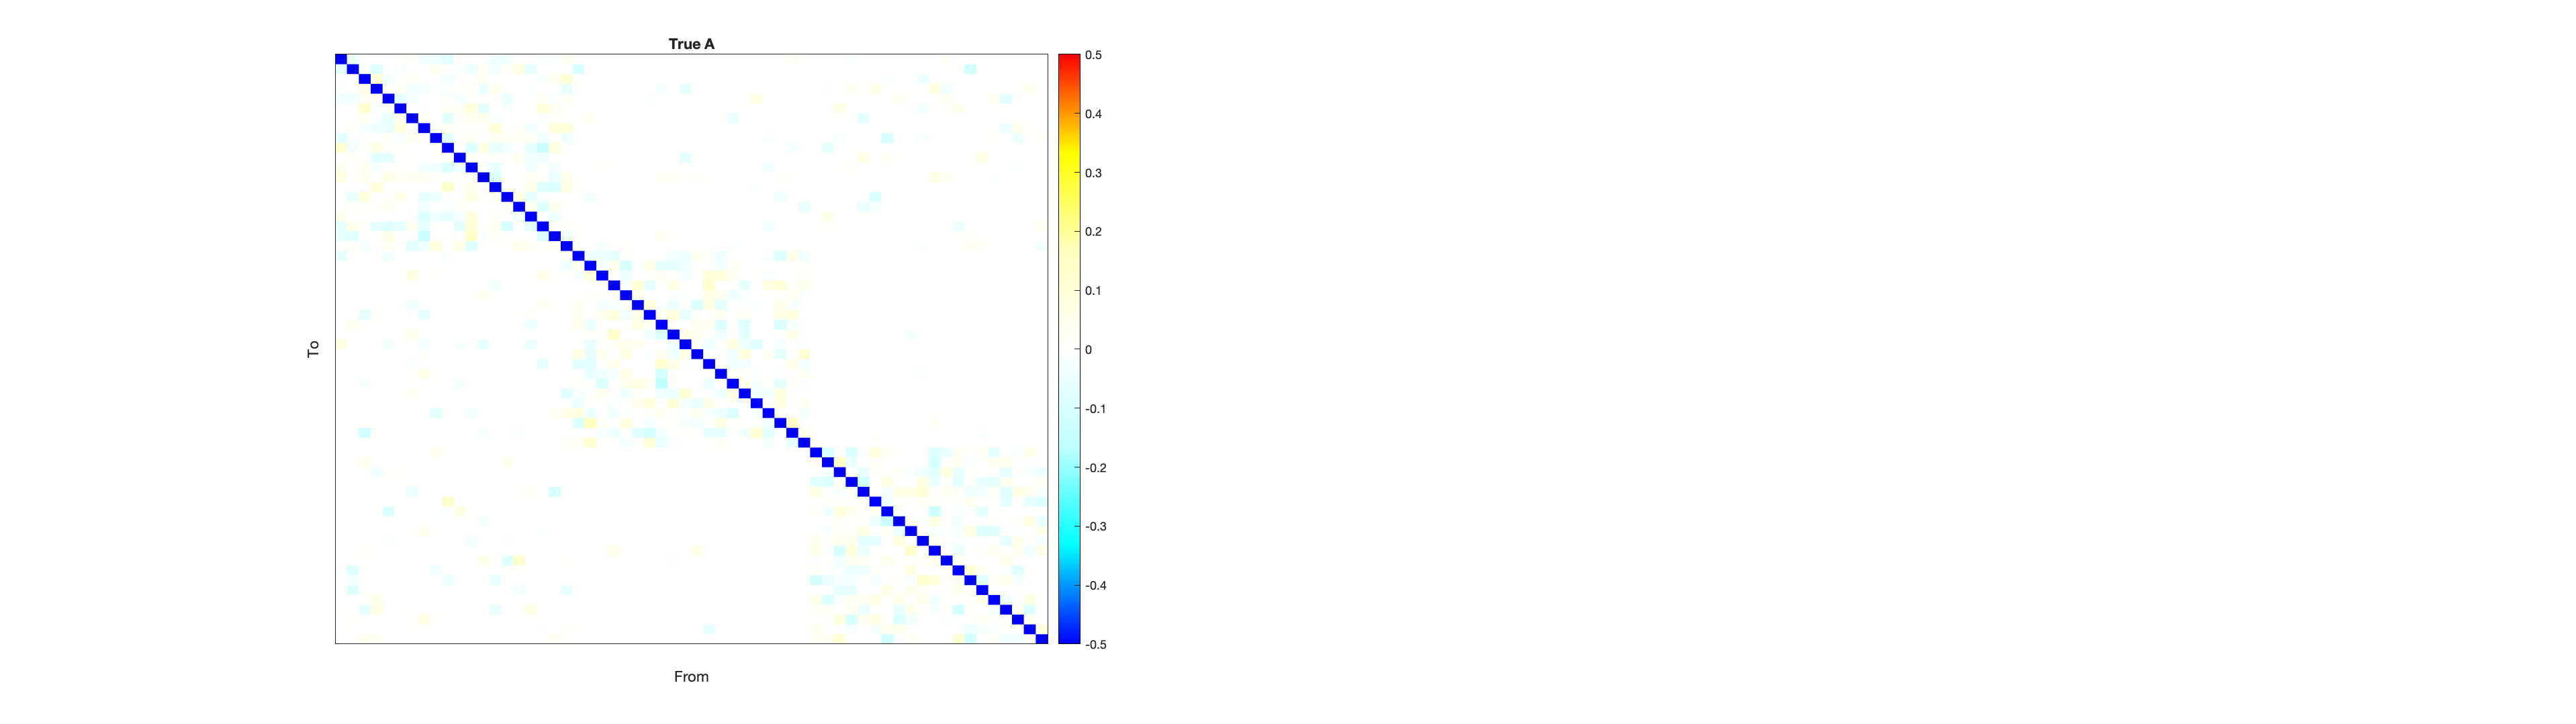

cmap = mycmap();   

f = figure();

subplot(1, 2, 1)
h = heatmap(stim_options.Tp.A);
h.CellLabelColor = 'none';
h.Colormap = cmap;

if (abs(min(min(stim_options.Tp.A))) > abs(max(max(stim_options.Tp.A))))
    col_lim = abs(min(min(stim_options.Tp.A)));
else
    col_lim = abs(max(max(stim_options.Tp.A)));
end

h.ColorLimits = [-1*col_lim col_lim];
title("True A"); 
xlabel("From");
ylabel("To");

grid(h, 'off');
h.XDisplayLabels = repmat(" ", size(stim_options.Tp.A, 1), 1);
h.YDisplayLabels = repmat(" ", size(stim_options.Tp.A, 1), 1);

set(f,'Units','normalized','Position',[0 0 1 .5]); 

Bursty task failed on dense network with primarily excitatory connections.

Impulse failed on dense network with primarily excitatory connections.

Impulse worked on dense network with excitatory and inhibitory connections coming from one distribution centered at 0.

tasktiming = [zeros(1, 88), 1, zeros(1, 4000)];
stim_options.u_dt = stim_options.TR/16;

stim_options.stim_node = 1:5;
stim_options.u = zeros(length(tasktiming), stim_options.n);
for i=1:length(stim_options.stim_node)
    stim_options.u(:, stim_options.stim_node(i)) = tasktiming;
end

% f = figure();
% plot(stim_options.u)

[DCM, options] = make_task_fmri(stim_options);

if sum(sum(isnan(DCM.Y.y))) > 0
    fprintf("Failed!");
else
    fprintf("Worked!");
end

Worked!

Plot activity by community

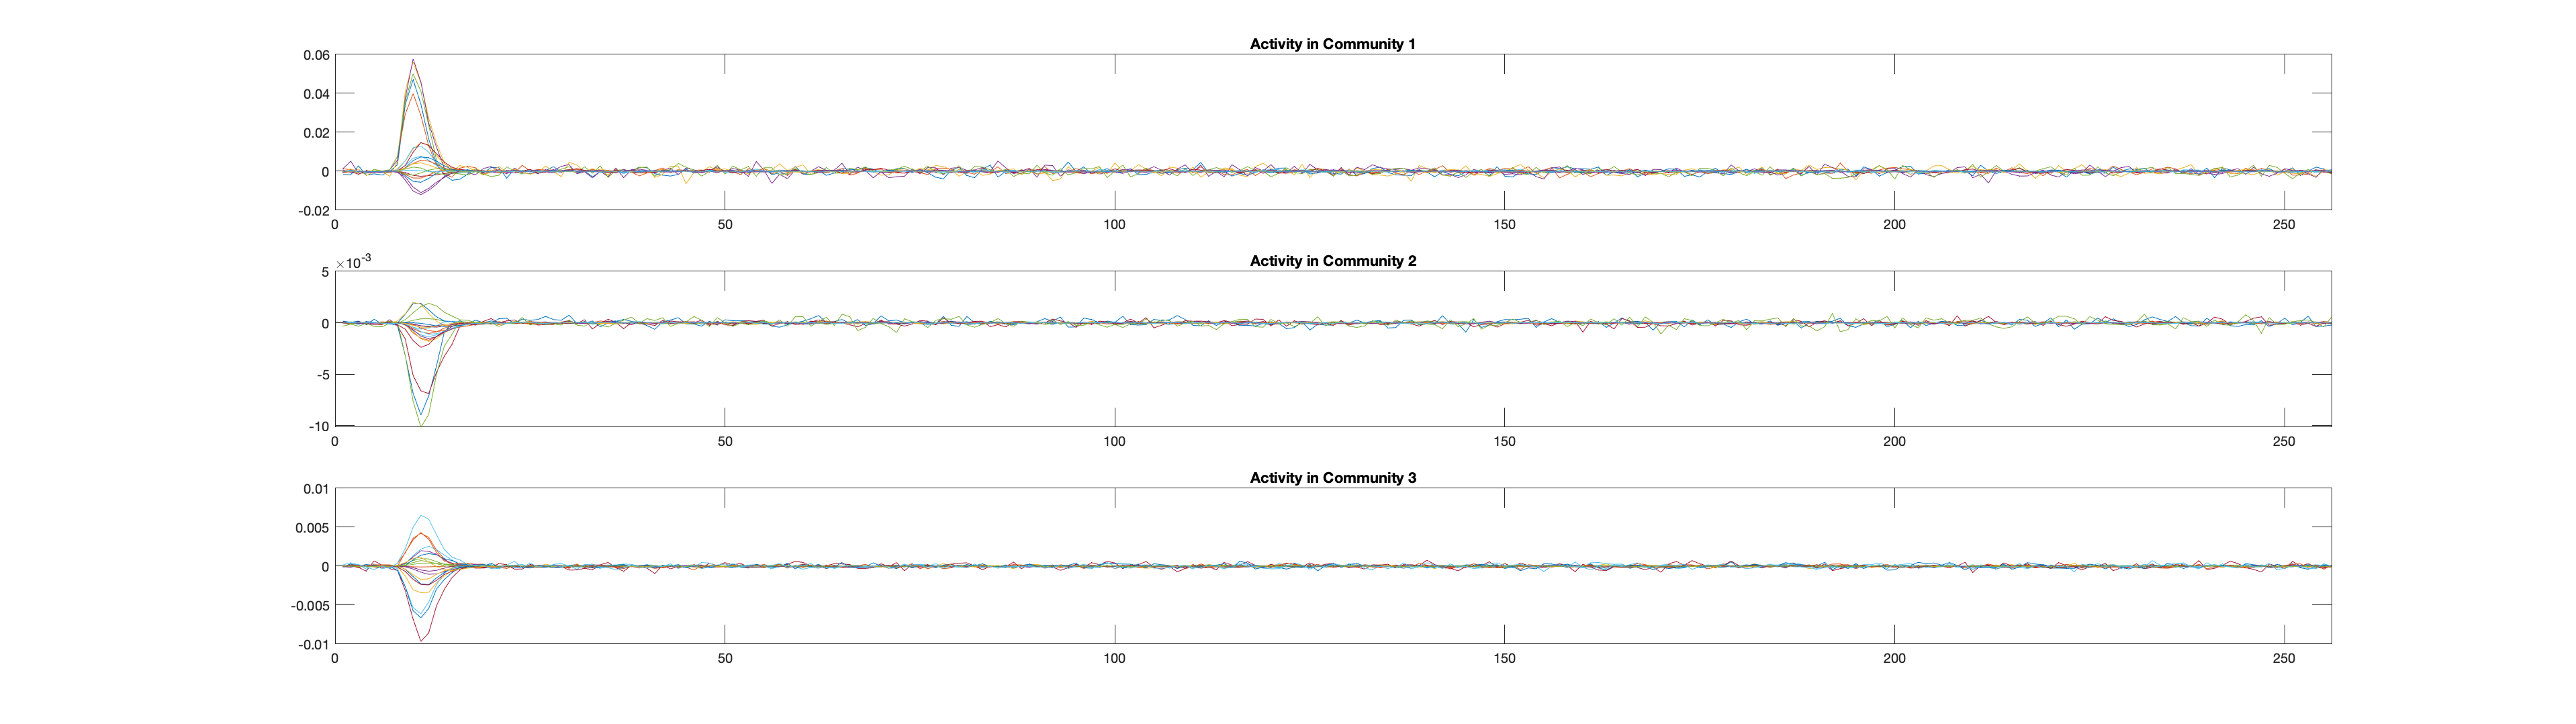

for i=1:stim_options.num_comms
    subplot(stim_options.num_comms, 1, i)
    plot(DCM.Y.y(:,(i-1)*stim_options.num_nodes_per_comm+1:i*stim_options.num_nodes_per_comm))
    title(sprintf("Activity in Community %.0f", i));
    xlim([0, length(DCM.Y.y)])
end